load("data.mat");
dat = data(:,1);

%tutaj znajde czestotliwosc
res = resample(dat,120,24)

res =    -0.0031
   -0.0021
   -0.0005
    0.0014
    0.0033
    0.0047
    0.0056
    0.0059
    0.0057
    0.0052


dow = downsample(res,6)

dow =    -0.0031
    0.0056
    0.0043
    0.0017
   -0.0109
   -0.0031
   -0.0049
   -0.0098
    0.0003
   -0.0116


y = fft(dow)

y = 1.0e+03 *

  -0.0013 + 0.0000i
   0.0322 + 0.0053i
  -0.0825 + 0.0129i
   0.1050 - 0.0279i
  -0.0917 + 0.0726i
   0.0477 - 0.0867i
  -0.0017 + 0.0412i
  -0.0317 + 0.0168i
   0.0336 - 0.0227i
   0.0042 + 0.0242i


fs = 2000000

fs = 2000000

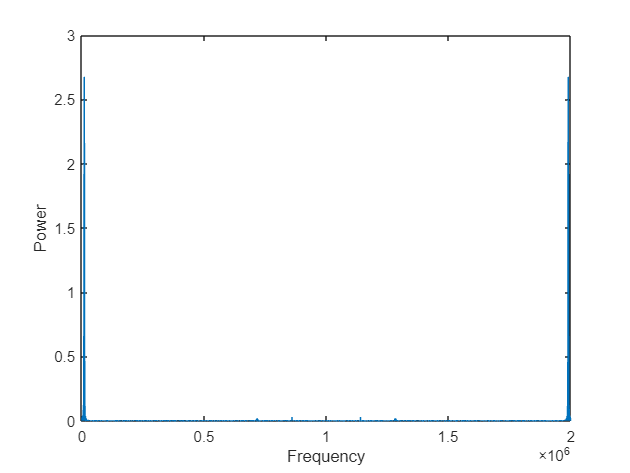

n = length(y);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT

plot(f,power)
xlabel('Frequency')
ylabel('Power')

% jeden long - 1520
% zero long - 1540
% jeden short - 750 
% zero short - 780

% preambula
% jeden - 750
% zero - 780
% przerwa - 7660 

% 390 =  1/f * 2000000
f = 2000000 / 390

f = 5.1282e+03

% f = 5128 Hz